% Question 5
n2aa = nt2aa('agttgccgacgcgcncar','ACGTOnly', false)

n2aa = 'SCRRAQ'

a2nt = aa2nt('TYNYMRQLVVDVVITNHYSV')

a2nt = 'ACATATAACTATATGCGCCAACTCGTGGTTGACGTGGTCATCACCAATCACTACAGTGTG'

d2r  = dna2rna('TTATGACGTTATTCTACTTTGATTGTGCGA')

d2r = 'UUAUGACGUUAUUCUACUUUGAUUGUGCGA'

r2d  = rna2dna ('ACGAUGAGUCAUGCUU')

r2d = 'ACGATGAGTCATGCTT'

% Question 6
Data = getgenbank('U15422')

Error using webread (line 122)
The connection to URL 'https://eutils.ncbi.nlm.nih.gov/entrez/eutils/esearch.fcgi?db=nuccore&term=U15422%5BAccession%5D' timed out after 5.000 seconds. The reason is "Resolving timed out after 5049 milliseconds". Perhaps the server is not responding or weboptions.Timeout needs to be set to a higher value.

Error in getncbidata>accession2gi (

seqviewer(Data)

% Question 12
load('primates.mat')
data = {'German_Neanderthal'      'AF011222';
        'Russian_Neanderthal'     'AF254446';
        'European_Human'          'X90314'  ;
        'Mountain_Gorilla_Rwanda' 'AF089820';
        'Chimp_Troglodytes'       'AF176766';
       };
% for ind = 1:length(data)
%     seqs(ind).Header   = data{ind,1};
%     seqs(ind).Sequence = getgenbank(data{ind,2},'sequenceonly','true');
% end
distances = seqpdist(primates,'Method','Jukes-Cantor','Alpha','DNA');
UPGMAtree = seqlinkage(distances,'UPGMA',primates)

    Phylogenetic tree object with 12 leaves (11 branches)


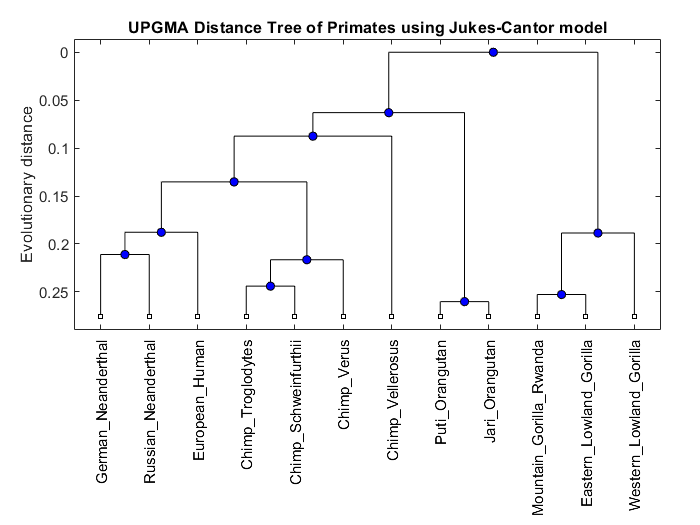


h = plot(UPGMAtree,'orient','top');
title('UPGMA Distance Tree of Primates using Jukes-Cantor model');
ylabel('Evolutionary distance')

% Question 13
cellseq = { 'TTGGTT' , 'TTTGGG' , 'TGGTTGGT' , 'GGGTTT' } ;
cellseq

cellseq = 1×4 cell array
    {'TTGGTT'}    {'TTTGGG'}    {'TGGTTGGT'}    {'GGGTTT'}


comp = regexpi ( cellseq , 'TTT' ) ; 
comp

comp = 1×4 cell array
    {0×0 double}    {[1]}    {0×0 double}    {[4]}


ind = find (cellfun( 'isempty' , comp ) ) ; 
celsq = cellseq (ind )

celsq = 1×2 cell array
    {'TTGGTT'}    {'TGGTTGGT'}


% Question 15
seq1 = 'ATTA' ;
seq2 = 'ATTTA' ; 
seq3 = 'ATTTAA' ; 
seqseq = char ( seq1 , seq2 , seq3 );
seqseq

seqseq = 3×6 char array
    'ATTA  '
    'ATTTA '
    'ATTTAA'
